*This tutorial is very roughly based on the book "TimeSeries Analysis and Its Applications" by Shumway and Stoffer.*

## **There are many kinds of time series data**

Usually we are either interested in the trend  or lagged relationships (time domain approach) or the periodicity (Fourier domain approach). Here we will look at signals and their autocorrelation. 

Autocorrelations tell you how correlated each time point is with other time points of varying lags.

**Speech data - time & Fourier domain**

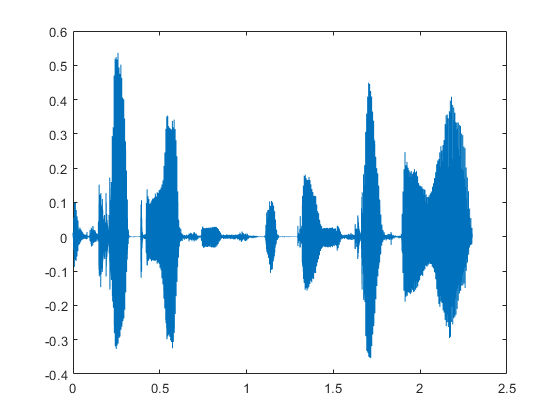

[speech,Fs] = audioread('female_talking.wav');
speech=speech(10*Fs:12.3*Fs);
sound(speech,Fs);

figure();
plot(linspace(0, 2.3, length(speech)), speech);

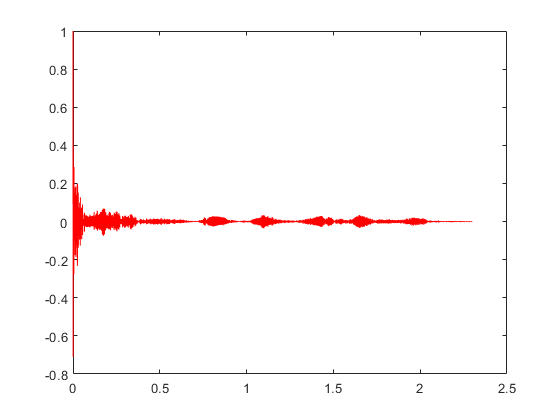


[acorr, lag] = autocorr(speech, length(speech)-1);
figure()
plot(lag/Fs, acorr, 'r');

*So this signal has periodicity, but not regular periodicity. Which is the better way to characterize this signal -  autoregression or the Fourier domain?*

**fMRI data - Fourier domain**

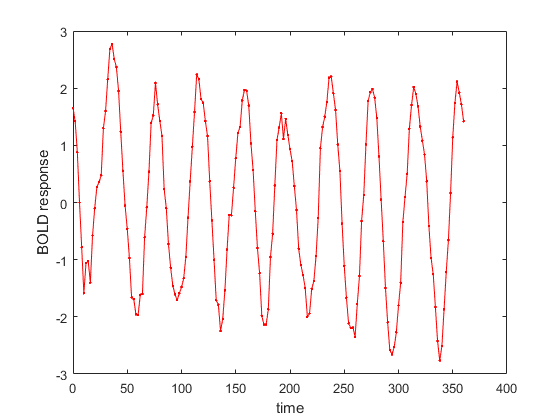


t_fmri=0:2:360; % data collected every 2s, for 6 min
w_fmri=randn(size(t_fmri)); % traditional white noise, example 1.8
aw_fmri = movmean(w_fmri, 6);

ts_fmrisignal=2*cos((2 * pi*(t_fmri+4))/40);
%figure()
plot(  t_fmri, ts_fmrisignal + aw_fmri, 'r.-'); 

xlabel('time'); ylabel('BOLD response');

[acorrS, lag] = autocorr(ts_fmrisignal , 5);
[acorrSN, ~] = autocorr(ts_fmrisignal +aw_fmri, 40);
[acorrN, lag] = autocorr(aw_fmri, 40);
figure()
%plot(lag*2, acorrS, 'k'); hold on
%plot(lag*2, acorrSN, 'b'); hold on
%plot(lag*2, acorrN, 'r'); hold on
%xlabel('lag'); ylabel('AC fmri')


*What happens if you do autoregression on ts_fmrisignal + w_fmri or ts_fmrisignal + aw_fmri?*

*What happens if you collect fMRI data every 3 seconds or 5 seconds instead of every 2 seconds? (change t_fmri=0:2:360; to t_fmri=0:5:360).*

**Developmental data - Time domain**

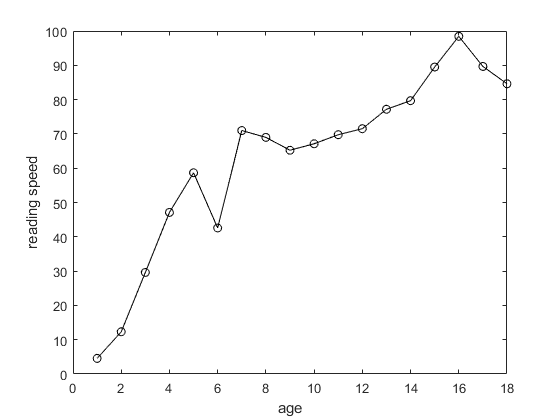

figure();figure('Name', 'reading speed')
t=1:18;
readingspeed = 30 * log(t);
wt = 10 * randn(size(readingspeed));
plot(t, readingspeed + wt, 'ko-'); xlabel('age'); ylabel('reading speed');

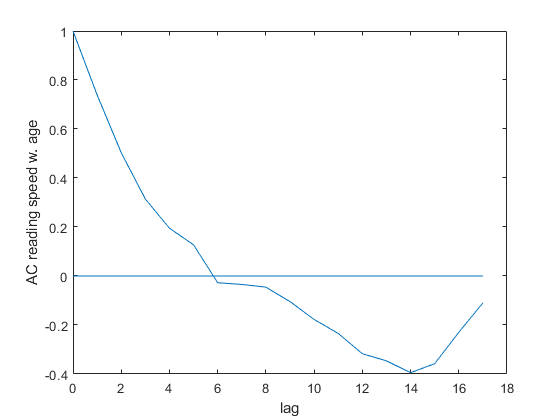


[tmp, lag] = autocorr(readingspeed + wt);
plot(lag, tmp); hold on;
l = line(lag, zeros(size(lag))); xlabel('lag'); ylabel('AC reading speed w. age');

*What happens  to the autocorrelation if you lower the noise (wt<10). If you increase it? Why?*

**Moving averages (spike count averages)**

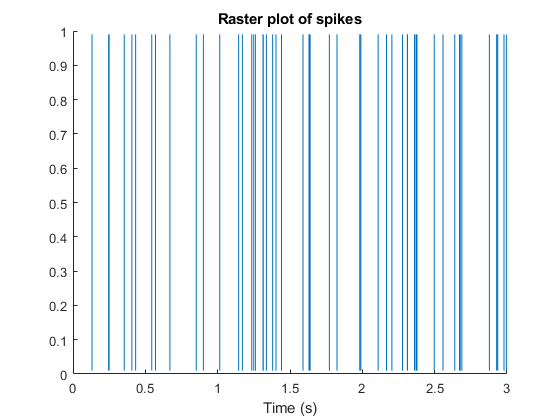

figure(); figure('Name', 'spikes')
timeStepS = 0.001;                  % 1 msec
spikesPerS = 20;                    % 50 spikes per second, on average
durationS = 3.000;                  % 1 sec simulation
times = 0:timeStepS:durationS;	% a vector with each time step	
vt = rand(size(times));
spikes = (spikesPerS*timeStepS) > vt;
trains = size(spikes, 1); 
ticMargin = 0.01;  
ticHeight = (1.0 - (trains + 1) * ticMargin) / trains;

times = [0:timeStepS:timeStepS * (length(spikes) - 1)];
for train = 1:size(spikes, 1)
    spikeTimes = find(spikes(train, :) == 1);
    yOffset = ticMargin + (train - 1) * (ticMargin + ticHeight);
    for i = 1:length(spikeTimes)
        line([spikeTimes(i), spikeTimes(i)]/1000, [yOffset, yOffset + ticHeight]);
    end
end
xlabel('Time (s)')
title('Raster plot of spikes');

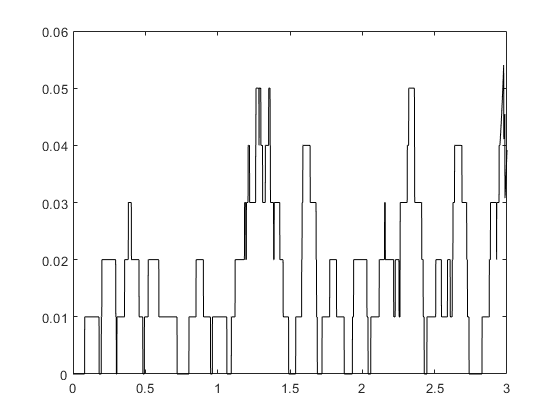


figure()
ave_spikes = movmean(spikes, 100);
plot(times, ave_spikes, 'k-');

*Calculate the autocorrelation for spikes and for ave_spikes. Why are they different?*

**Random walk**

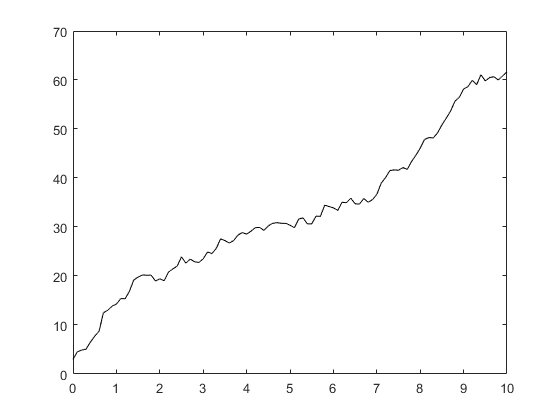

t=0:.1:10;
w=randn(size(t));
d=.5;
clear x
x(1)=3;
for i=2:length(t)
    x(i)=d+x(i-1)+w(i);
end
figure(); title('random walk');
plot(t, x, 'k-');

*Draw a prediction for the autocorrelation. Then see if you were right*

**What differentiates time series data from repeated measurements?**

Either the data or the noise has a temporal dependency. I.e. the indexing in time has importance.

Although time series are often continuous, nowaways they are usually approximated by discrete functions

**Temporal dependencies**

Can be due to the use of a moving average or filtering (i.e. the measurement induces dependencies)

Can be due to dependencies in the signal or noise; each time point depends on the previous time point - e.g. autoregression models, random walk with drift, or a cyclical model.

*Take white noise and look at the autocorrelation function. Then smooth it. What happens to the autocorrelation function - why?*